## Huen's Method for Numerically Integrating ODE's

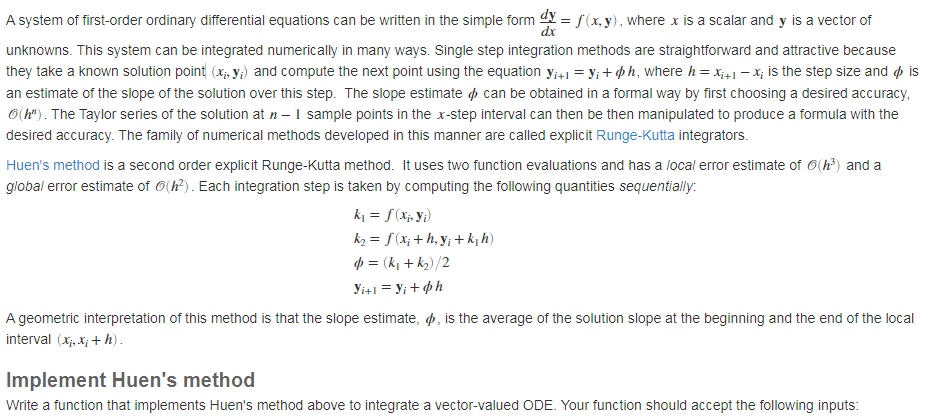

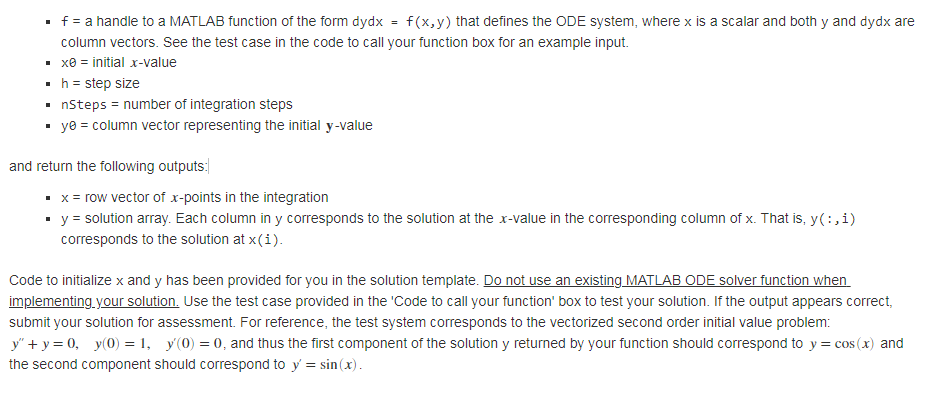

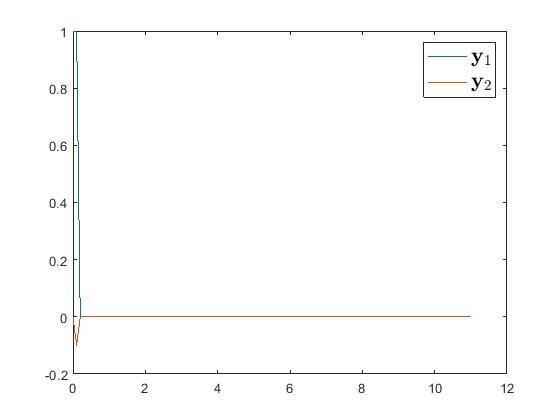

f = @(x,y) [y(2); -y(1)]; % ODE function
x0 = 0; h = 0.1; nSteps = 11; y0 = [1; 0]; % Initial condition and solver parameters
[x,y] = odeHeun(f,x0,h,nSteps,y0);
plot(x,y)
legend({'$\mathbf{y}_1$','$\mathbf{y}_2$'},'Interpreter','latex','FontSize',16)

function [x,y] = odeHuen(f,x0,h,nSteps,y0)

    % Initialize the output solution arrays.
    m = length(y0);
    x = zeros(1,nSteps+1);
    y = zeros(m,nSteps+1);
    x(1) = x0;
    y(:,1) = y0;
    
    % Compute x an y by integrating the ODE system using Huen's method. 
    cond=true;
    i=1;
    
    while cond
        k1=f(x(i),y(:,i));
        k2=f(x(i)+h,y(:,i)+k1*h);
        the=(k1+k2)/2;
        y(:,i+1)=y(:,i)+the*h;
        x(i+1)=x(i)+h;
        i=i+1;
        cond=i<=nSteps;
    end


end
